DSP Laboratory S 01-02

Instructor: M.H. Shammakhi

Student: Dina Soltani Tehrani - 9523703

update1: 03/12/2021

# plot

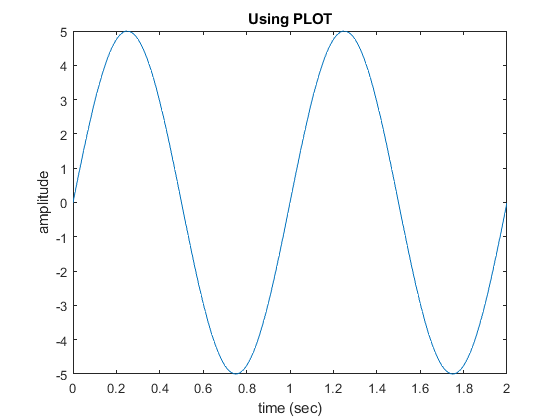


clc;
clear;
f=1; % Hz
A=5; % amplitude
t=0:0.01:2;
func=A*sin(2*pi*f*t);
plot(t,func)
xlabel("time (sec)");
ylabel("amplitude");
title("Using PLOT");

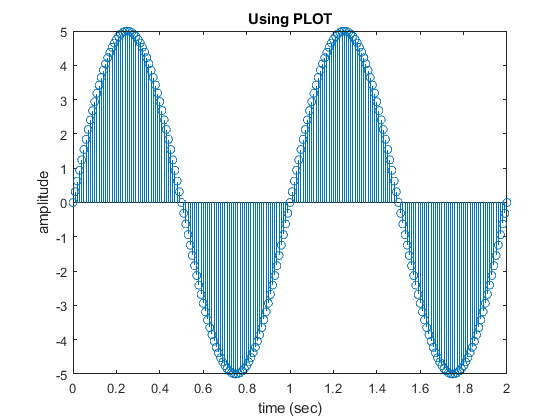

%% stem
clc;
clear;
f=1; % Hz
A=5; % amplitude
t=0:0.01:2;
func=A*sin(2*pi*f*t);
stem(t,func)
xlabel("time (sec)");
ylabel("amplitude");
title("Using PLOT");

## subplot

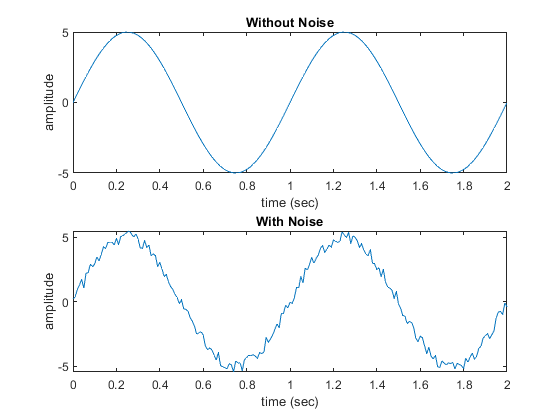

clc;
clear;
f=1; % Hz
A=5; % amplitude
t=0:0.01:2;
func3=A*sin(2*pi*f*t);
n= -0.5 + 1.*rand(201,1);
nfunc=zeros(1,201);
for i=1:201
   nfunc(1,i)=func3(1,i)+n(i,1);    
end
subplot(2,1,1)
plot(t,func3)
xlabel("time (sec)");
ylabel("amplitude");
title("Without Noise");
subplot(2,1,2)
plot(t,nfunc)
xlabel("time (sec)");
ylabel("amplitude");
title("With Noise");

## conv

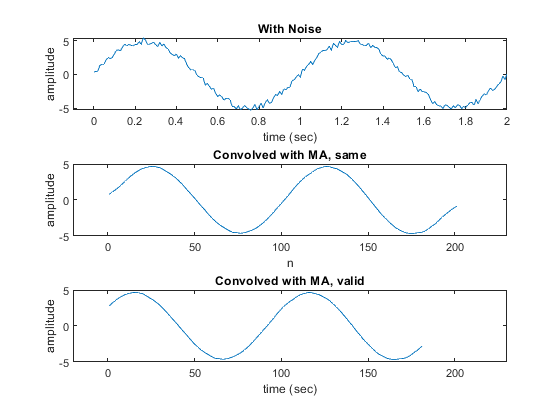

clc;
clear;
f=1; % Hz
A=5; % amplitude
t=0:0.01:2;
t2=0:0.01:2.1;
func=A*sin(2*pi*f*t);
n= -0.5 + 1.*rand(201,1);
nfunc=zeros(1,201);
for i=1:201
   nfunc(1,i)=func(1,i)+n(i,1);    
end
M1=0;
M2=20;
h=(1/(M1+M2+1))*ones(1,21);
n_ma_same=conv(nfunc,h,'same');
n_ma_valid=conv(nfunc,h,'valid');
subplot(3,1,1)
plot(t,nfunc)
xlabel("time (sec)");
ylabel("amplitude");
title("With Noise");
xlim([-0.1,2])

## conv M1=0; M2=20; full, same, valid

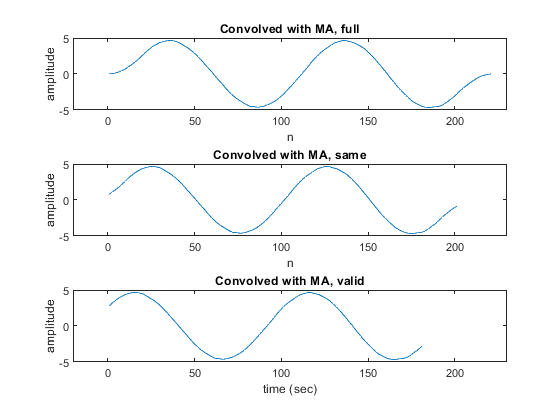

clc;
clear;
f=1; % Hz
A=5; % amplitude
t=0:0.01:2;
func=A*sin(2*pi*f*t);
n= -0.5 + 1.*rand(201,1);
nfunc=zeros(1,201);
for i=1:201
   nfunc(1,i)=func(1,i)+n(i,1);    
end
M1=0;
M2=20;
h=(1/(M1+M2+1))*ones(1,21);
n_ma_full=conv(nfunc,h,'full');
n_ma_same=conv(nfunc,h,'same');
n_ma_valid=conv(nfunc,h,'valid');
subplot(3,1,1)
plot(n_ma_full)
xlabel("n");
ylabel("amplitude");
title("Convolved with MA, full");
xlim([-20,230])
subplot(3,1,2)
plot(n_ma_same)
xlabel("n");
ylabel("amplitude");
title("Convolved with MA, same");
xlim([-20,230])
subplot(3,1,3)
plot(n_ma_valid)
xlabel("time (sec)");
ylabel("amplitude");
title("Convolved with MA, valid");
xlim([-20,230])

Based on the plots, full displays the whole convolved signal, same, an output of the same length with the input signal, and valid, an output only for the common valid section. 

## conv M1=0; M2=20; full, same, valid, time-plotted

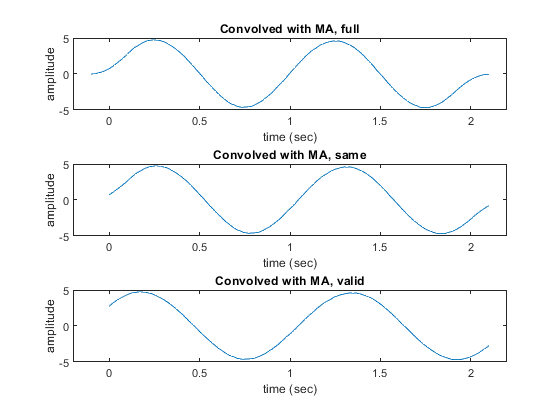

clc;
clear;
f=1; % Hz
A=5; % amplitude
t=0:0.01:2;
t1=linspace(-0.1,2.1,221);
t2=linspace(0,2.1,201);
t3=linspace(0,2.1,181);
func=A*sin(2*pi*f*t);
n= -0.5 + 1.*rand(201,1);
nfunc=zeros(1,201);
for i=1:201
   nfunc(1,i)=func(1,i)+n(i,1);    
end
M1=0;
M2=20;
h=(1/(M1+M2+1))*ones(1,21);
n_ma_full=conv(nfunc,h,'full');
n_ma_same=conv(nfunc,h,'same');
n_ma_valid=conv(nfunc,h,'valid');
subplot(3,1,1)
plot(t1,n_ma_full)
xlabel("time (sec)");
ylabel("amplitude");
title("Convolved with MA, full");
xlim([[-0.2,2.2]])
subplot(3,1,2)
plot(t2,n_ma_same)
xlabel("time (sec)");
ylabel("amplitude");
title("Convolved with MA, same");
xlim([[-0.2,2.2]])
subplot(3,1,3)
plot(t3,n_ma_valid)
xlabel("time (sec)");
ylabel("amplitude");
title("Convolved with MA, valid");
xlim([-0.2,2.2])

## filter

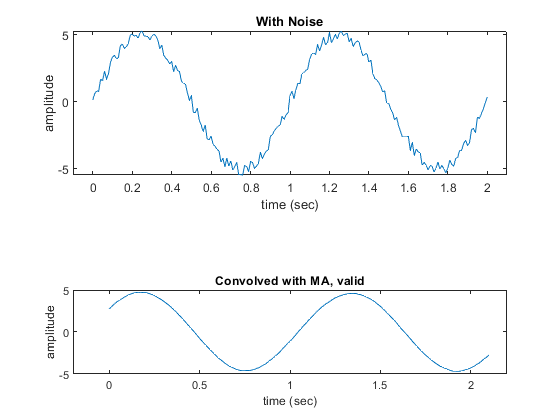

clc;
clear;
f=1; % Hz
A=5; % amplitude
t=0:0.01:2;
func=A*sin(2*pi*f*t);
n= -0.5 + 1.*rand(201,1);
nfunc=zeros(1,201);
for i=1:201
   nfunc(1,i)=func(1,i)+n(i,1);    
end
M1=0;
M2=20;
windowsize= M1+M2+1;
b=(1/(M1+M2+1))*ones(1,21);
a=1;
filtered_f=filter(b,a,nfunc);
subplot(2,1,1)
plot(t,nfunc)
xlabel("time (sec)");
ylabel("amplitude");
title("With Noise");
xlim([-0.1,2.1])

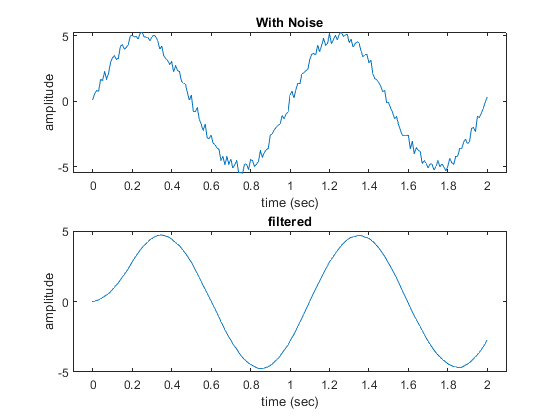

subplot(2,1,2)
plot(t,filtered_f)
xlabel("time (sec)");
ylabel("amplitude");
title("filtered");
xlim([-0.1,2.1])

Filter acts like the 'same' condition when using conv.

## Aliasing in Time

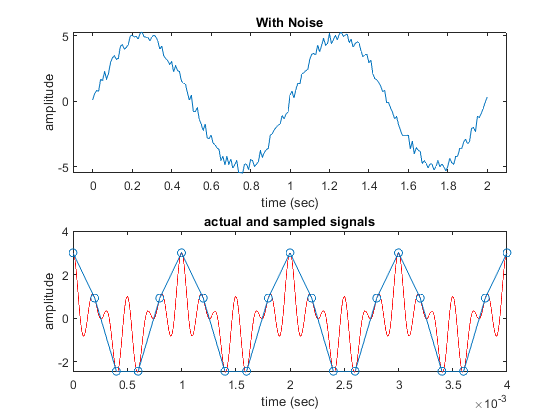

clc;
clear;
f1=1000;
f2=4000;
f3=6000;
ta=0:0.00000001:0.004;
ts=0:(1/5000):0.004;
xs=cos(2*pi*f1*ts) + cos(2*pi*f2*ts) + cos(2*pi*f3*ts);
xa=cos(2*pi*f1*ta) + cos(2*pi*f2*ta) + cos(2*pi*f3*ta);

plot(ta,xa,'r')
hold on
plot(ts,xs,'-o')
xlabel("time (sec)");
ylabel("amplitude");
title("actual and sampled signals");

## Aliasing in Time

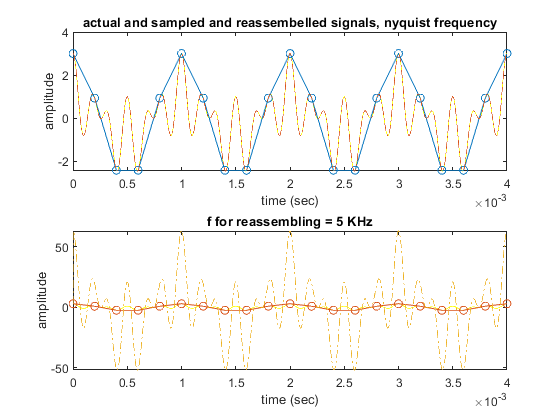

clc;
clear;
rng default
f1=1000; f2=4000; f3=6000;
fc=5000;

ta=0:0.00000001:0.004;
ts=0:(1/fc):0.004;

xs=cos(2*pi*f1*ts) + cos(2*pi*f2*ts) + cos(2*pi*f3*ts);
xa=cos(2*pi*f1*ta) + cos(2*pi*f2*ta) + cos(2*pi*f3*ta);

h1=sinc(0:(1/2*fc):0.004);
rsignal1= filter(h1,1,xa);

h2=sinc(0:(1/fc):0.004);
rsignal2= filter(h2,1,xa);

subplot(2,1,1)
plot(ta,xa,'y')
hold on
plot(ts,xs,'-o')
hold on
plot(ta,rsignal1,'-.')
xlabel("time (sec)");
ylabel("amplitude");
title("actual and sampled and reassembelled signals, nyquist frequency");
subplot(2,1,2)
plot(ta,xa,'y')
hold on
plot(ts,xs,'-o')
hold on
plot(ta,rsignal2,'-.')
xlabel("time (sec)");
ylabel("amplitude");
title("f for reassembling = 5 KHz");

When reassembling the samplled signal without paying attention to the nyquist frequency, we would be unable to detect the exact actual signal; however, by considering the nyquist frequency or more, the actual signal would almost perfectly be detected.

## Aliasing in Frequency

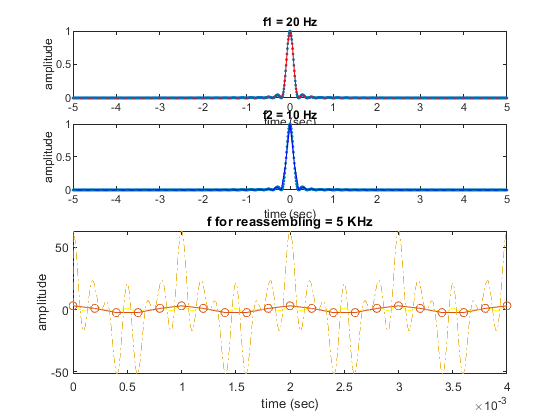

clc;
clear;
f1=20; f2=10; f3=5; f4=4;
ta= -5:0.01:5;
ts1= -5:(1/f1):5;
ts2= -5:(1/f2):5;
ts3= -5:(1/f3):5;
ts4= -5:(1/f4):5;

xa=(sinc(5*ta)).^2;
x1=(sinc(5*ts1)).^2;
x2=(sinc(5*ts2)).^2;
x3=(sinc(5*ts3)).^2;
x4=(sinc(5*ts4)).^2;

subplot(4,1,1)
plot(ta,xa,'.-')
hold on
plot(ts1,x1,'r')
xlabel("time (sec)");
ylabel("amplitude");
title("f1 = 20 Hz");

subplot(4,1,2)
plot(ta,xa,'.-')
hold on
plot(ts2,x2,'b')
xlabel("time (sec)");
ylabel("amplitude");
title("f2 = 10 Hz");

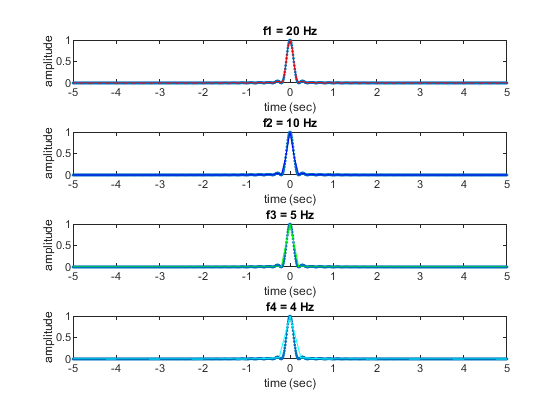


subplot(4,1,3)
plot(ta,xa,'.-')
hold on
plot(ts3,x3,'g')
xlabel("time (sec)");
ylabel("amplitude");
title("f3 = 5 Hz");

subplot(4,1,4)
plot(ta,xa,'.-')
hold on
plot(ts4,x4,'c')
xlabel("time (sec)");
ylabel("amplitude");
title("f4 = 4 Hz");

The plots show that the more the sampling frequency, the more accurate the resultant signal.

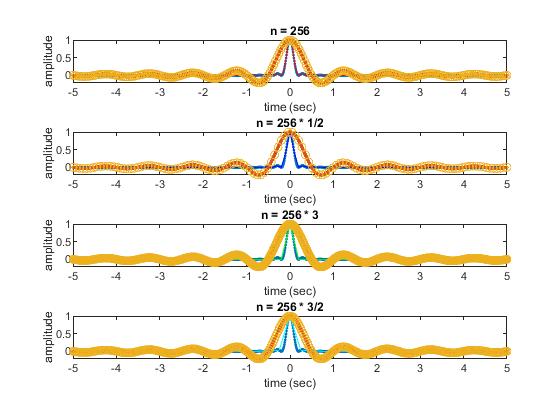

clc;
clear;
n1=256; n2=0.5*n1; n3=3*n1; n4=1.5*n1;
ta= -5:0.001:5;
ts1=linspace(-5,5,n1);
ts2=linspace(-5,5,n2);
ts3=linspace(-5,5,n3);
ts4=linspace(-5,5,n4);

xa=sinc(2*ta);
x1=sinc(2*ts1);
x2=sinc(2*ts2);
x3=sinc(2*ts3);
x4=sinc(2*ts4);

subplot(4,1,1)
plot(ta,xa,'.')
hold on
plot(ts1,x1,'o')
xlabel("time (sec)");
ylabel("amplitude");
title("n = 256");

subplot(4,1,2)
plot(ta,xa,'.')
hold on
plot(ts2,x2,'o')
xlabel("time (sec)");
ylabel("amplitude");
title("n = 256 * 1/2");

subplot(4,1,3)
plot(ta,xa,'.')
hold on
plot(ts3,x3,'o')
xlabel("time (sec)");
ylabel("amplitude");
title("n = 256 * 3");

subplot(4,1,4)
plot(ta,xa,'.')
hold on
plot(ts4,x4,'o')
xlabel("time (sec)");
ylabel("amplitude");
title("n = 256 * 3/2");

In the two following scripts, I didn't have plotted the spectrums which are added to the current version.

% Frequency Aliasing edited
clc;
clear;
n1=256; n2=0.5*n1; n3=3*n1; n4=1.5*n1;
ta= -5:0.001:5;
ts1=linspace(-5,5,n1);
ts2=linspace(-5,5,n2);
ts3=linspace(-5,5,n3);
ts4=linspace(-5,5,n4);

xa=sinc(2*ta);
x1=sinc(2*ts1);
x2=sinc(2*ts2);
x3=sinc(2*ts3);
x4=sinc(2*ts4);

w=linspace(-2*pi,2*pi,128);

za=freqz(xa,1,w);
z1=freqz(x1,1,w);
z2=freqz(x2,1,w);
z3=freqz(x3,1,w);
z4=freqz(x4,1,w);

subplot(4,1,1)
plot(w/pi,log(log(abs(za))),'.')

hold on
plot(ta,xa,'o')
hold on
plot(w/pi,log(abs(z1)),'.')
hold on
plot(ts1,x1,'o')
xlabel("frequency");
ylabel("amplitude");
title("n = 256");

subplot(4,1,2)
plot(w/pi,log(log(abs(za))),'.')

hold on
plot(ta,xa,'o')
hold on
plot(w/pi,log(abs(z2)),'.')
hold on
plot(ts2,x2,'o')
xlabel("time (sec)");
ylabel("amplitude");
title("n = 256 * 1/2");

subplot(4,1,3)
plot(w/pi,log(log(abs(za))),'.')

hold on
plot(ta,xa,'o')
hold on
plot(w/pi,log(abs(z3)),'.')
hold on
plot(ts3,x3,'o')
xlabel("time (sec)");
ylabel("amplitude");
title("n = 256 * 3");

subplot(4,1,4)
plot(w/pi,log(log(log(abs(za)))),'r')

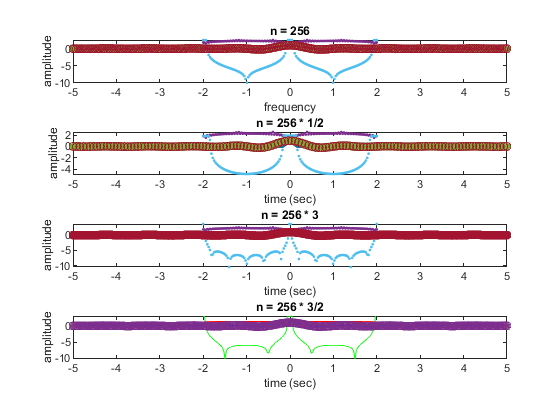

hold on
plot(ta,xa,'b')
hold on
plot(w/pi,log(abs(z4)),'g')
hold on
plot(ts4,x4,'o')
xlabel("time (sec)");
ylabel("amplitude");
title("n = 256 * 3/2");

clc;
clear;
%% Aliasing in Frequency
f1=20; f2=10; f3=5; f4=4;
ta= -5:0.01:5;
ts1= -5:(1/f1):5;
ts2= -5:(1/f2):5;
ts3= -5:(1/f3):5;
ts4= -5:(1/f4):5;

xa=(sinc(5*ta)).^2;
x1=(sinc(5*ts1)).^2;
x2=(sinc(5*ts2)).^2;
x3=(sinc(5*ts3)).^2;
x4=(sinc(5*ts4)).^2;

w=linspace(-2*pi,2*pi,128);

za=freqz(xa,1,w);
z1=freqz(x1,1,w);
z2=freqz(x2,1,w);
z3=freqz(x3,1,w);
z4=freqz(x4,1,w);

subplot(4,1,1)
plot(ta,xa,'.-')
hold on
plot(ts1,x1,'r')
hold on
plot(w,za,'.-')

hold on
plot(w,z1,'r')


subplot(4,1,2)
plot(ta,xa,'.-')
hold on
plot(ts2,x2,'b')
hold on
plot(w,za,'.-')

hold on
plot(w,z2,'r')


subplot(4,1,3)
plot(ta,xa,'.-')
hold on
plot(ts3,x3,'g')
hold on
plot(w,za,'.-')

hold on
plot(w,z3,'r')


subplot(4,1,4)
plot(ta,xa,'.-')
hold on
plot(ts4,x4,'c')
hold on
plot(w,za,'.-')

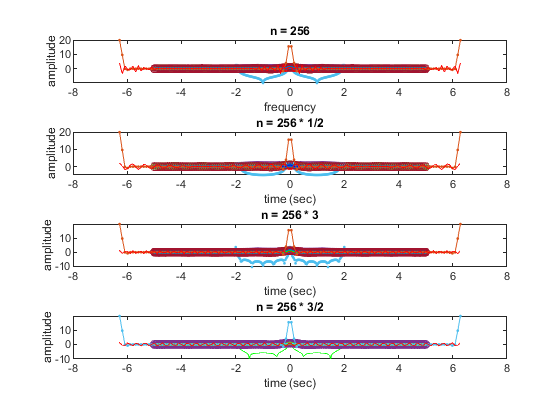

hold on
plot(w,z4,'r')

clc;
clear;
%% singen function
n=0:49;
w=linspace(0,pi,50);
x=zeros(50,50);
for i=1:50
    x(:,i)=singen(w(1,i),n);
end

clc;
clear;
%% DFT withou Matlab's built-in functions

t = linspace(-2*pi,2*pi,128);
f1=pi/16; f2=5*pi/16; f3=9*pi/16; f4=13*pi/16;
xt= cos(2*pi*f1*t) + cos(2*pi*f2*t) + cos(2*pi*f3*t) + cos(2*pi*f4*t);
tic
Xf_DFT=myDFT(xt);
toc;

Elapsed time is 0.036670 seconds.


tic
Xf_fft=fft(xt);
toc;

Elapsed time is 0.022855 seconds.


Xf_fftshift=fftshift(Xf_fft);

x_ifftshift=ifftshift(Xf_fft);
x_ifft=ifft(Xf_fft);


subplot(2,3,1)
plot(t,((Xf_DFT)),'r')

xlabel("frequency");
ylabel("amplitude");
title("DFT");
grid
subplot(2,3,2)
plot(t,((Xf_fft)),'b')

xlabel("frequency");
ylabel("amplitude");
title("fft");
grid
subplot(2,3,3)
plot(t,((Xf_fftshift)),'g')

xlabel("frequency");
ylabel("amplitude");
title("fftshift");
grid

subplot(2,3,4)
plot(t,((x_ifftshift)),'g')

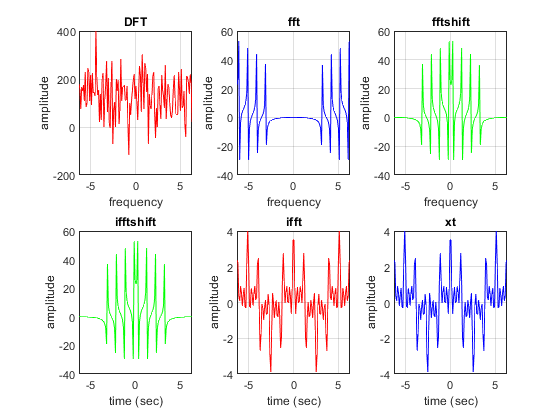

xlabel("time (sec)");
ylabel("amplitude");
title("ifftshift");
subplot(2,3,5)
plot(t,((x_ifft)),'r')
xlabel("time (sec)");
ylabel("amplitude");
title("ifft");
grid
subplot(2,3,6)
plot(t,((xt)),'b')
xlabel("time (sec)");
ylabel("amplitude");
title("xt");
grid

## Functions

function X=myDFT(x)
N=numel(x);
%X=zeros(1,N);
for k=1:N
    X(k)=sum(x.^exp(-1j*2*pi*k/N*(0:N-1)));
end
end

function x=singen(w0,n)
N=numel(n);
    for k=1:N
        x=(sin(w0.*n(1,:))).*ones(1,N);
    end
end